# Question #1 

(a) Create a Matlab code to plot the **minimum power **required and power available on the same plot as a function of altitude, given a set of aircraft characteristics.

 (b) Now use your code on the prop aircraft from your case study notes and paste your plot in your response.

 (c) Create a Matlab code to plot the **minimum thrust **required and thrust available on the same plot as a function of altitude, given a set of aircraft characteristics.

 (d) Use your code on the jet aircraft from your case study notes and paste your plot in your response. 

NOTE: Once you have written the code for power or thrust, you can easily adapt it for the thrust or power.

-- in this file the matlab functions **airDensity_cal.mlx**  ,** temp_cal.mlx**, **pressure_cal.mlx**, and** minPower_cal.mlx **are used

## **Part (a) & (b)**

## -- Preparation

% Adding path to enable the use of function in another directory 
doc = genpath('C:\Users\small\Desktop\classes\2019-spring\AAE251\hw9\matlab\functions');
addpath(doc);

prop_weight = 1315; % [kg]
prop_wingArea = 16.3; % [m^2] 
prop_dragPolar_coeff = 0.054;
prop_zeroLiftDraf_coeff = 0.026; 


## -- Main

% Calling out the function to obtain the air density for corresponding altitudes
altitude = 0:10000; % [m]
unit = 'SI'; % Indicating that the calculations are in SI units 

[density] = airDensity_cal(altitude,unit);

% Calling out the function to calculate the minimum power
[prop_P_min] = minPower_cal(density, prop_weight, prop_wingArea, ...
    prop_dragPolar_coeff, prop_zeroLiftDraf_coeff);


## -- Plotting

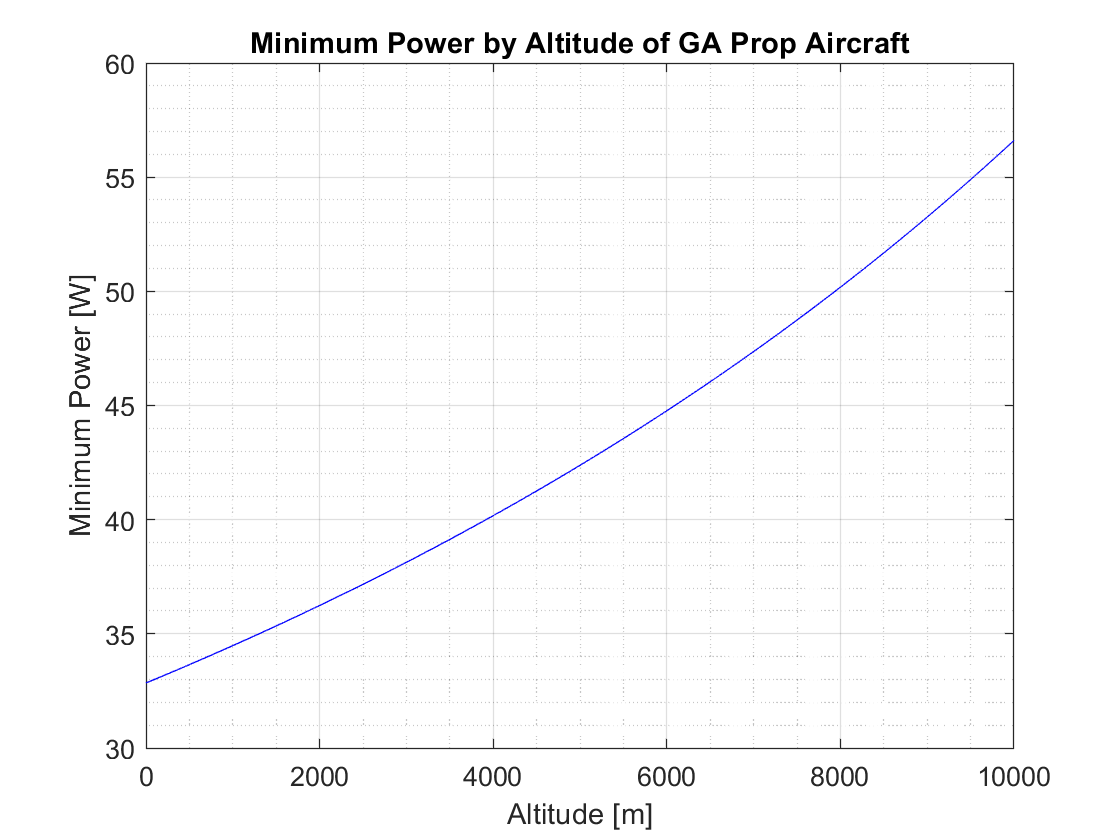

figure(1)
plot(altitude, prop_P_min, '-b')
title('Minimum Power by Altitude of GA Prop Aircraft')
xlabel('Altitude [m]')
ylabel('Minimum Power [W]')
grid on
grid minor
box on

## Part (c) & (d)

## -- Preparation

jet_weight = 33100; % [kg]
jet_wingArea = 88.2; % [m^2] 
jet_dragPolar_coeff = 0.05;
jet_zeroLiftDrag_coeff = 0.015; 

## -- Main

% Calling out the minimum thrust calculating function
[jet_T_min] = minThrust_cal(altitude, jet_weight, jet_dragPolar_coeff,...
    jet_zeroLiftDrag_coeff);

## Plotting

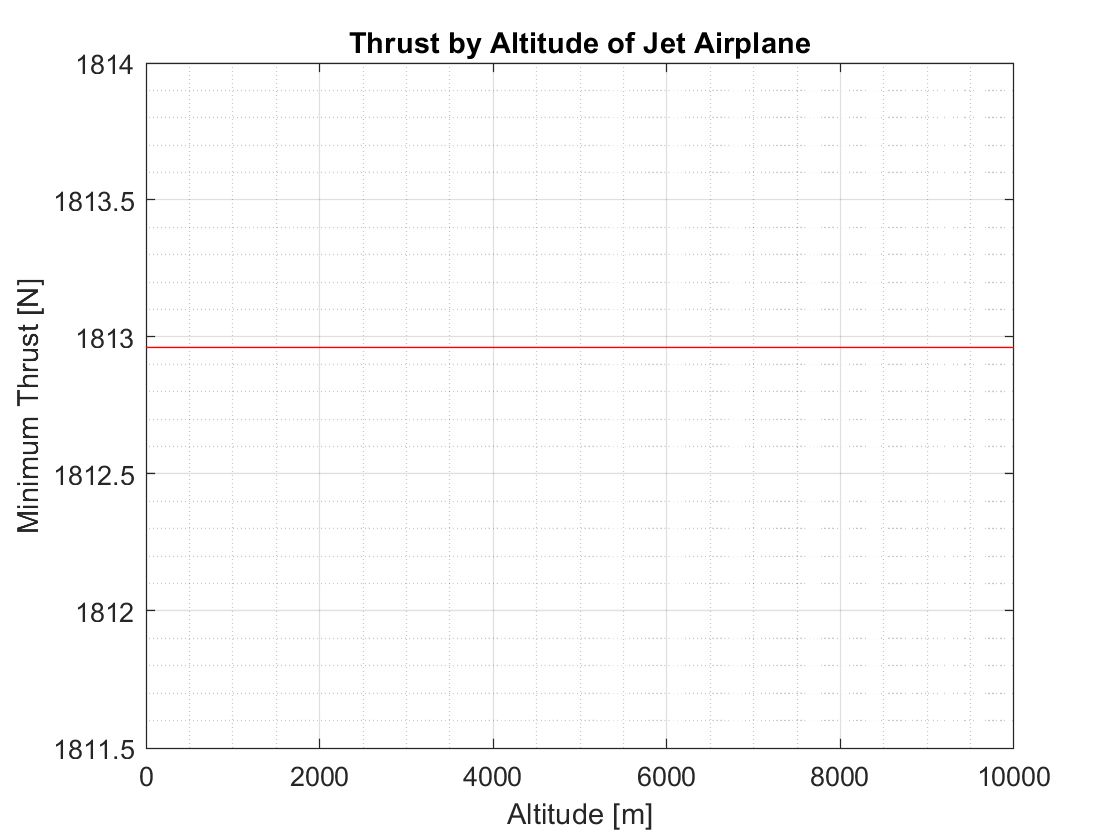

figure(2)
plot(altitude, jet_T_min, '-r')
title('Thrust by Altitude of Jet Airplane')
xlabel('Altitude [m]')
ylabel('Minimum Thrust [N]')
grid on 
grid minor
box on